%% === Setup ===
addpath('C:/Users/JINHWA/Projects/BrainNetworkTDA/ExternalPackages/PH-STAT-main/');

%% === Subject Lists ===
male_ids = {'100206', '102109', '131823', '112112', '130114'};
female_ids = {'102311', '100307', '111211', '102816', '128026'};

all_ids = [male_ids, female_ids];
n_male = length(male_ids);
n_female = length(female_ids);
n_total = n_male + n_female;

data_dir = 'C:/Users/JINHWA/Projects/BrainNetworkTDA/Usedata/rfMRI_ts/';
win_size = 60;

%% === Function: Load correlation vector and create distance matrix tensor ===
function D_tensor = load_corrvec_to_distance_tensor(file_path, win_size)
    V = readmatrix(file_path);
    n_series = size(V, 2);
    n_points = n_series - win_size + 1;
    D_all = cell(1, n_points);
    for t = 1:n_points
        X = V(:, t:t+win_size-1)';
        D = squareform(pdist(X, 'euclidean'));
        D = double(D);
        D(isnan(D) | isinf(D)) = 999;
        D(1:end+1:end) = 0;
        D = (D + D') / 2;
        D_all{t} = D;
    end
    D_tensor = cat(3, D_all{:});
end

%% === Load distance tensors for all subjects ===
D_all = cell(1, n_total);
for i = 1:n_total
    file = fullfile(data_dir, [all_ids{i}, '_REST1_LR_AAL_corr_vec.txt']);
    D_all{i} = load_corrvec_to_distance_tensor(file, win_size);
end

%% === Divide groups ===
D_male = cat(3, D_all{1:n_male});
D_female = cat(3, D_all{n_male+1:end});

%% === Compute Wasserstein distances using official PH-STAT function ===
loss = WS_pdist2(D_male, D_female);
D01 = loss.D01;
observed_stat = mean(D01(:));
fprintf("Observed mean squared Wasserstein distance (D01): %.4f\n", observed_stat);

Observed mean squared Wasserstein distance (D01): 24141.1031


%% === Compute Ratio Statistic ===
observed_ratio = WS_ratio(D01, n_male, n_female);
fprintf("Observed ratio statistic: %.4f\n", observed_ratio);

Observed ratio statistic: 5.6234



%% === Perform Transposition Test ===
n_trans = 10000;
perm_no = 1000;
[transStat, elapsedTimes] = WS_transpositions(D01, n_male, n_female, n_trans, perm_no);

%% === Compute p-value ===
p_value = sum(transStat >= observed_ratio) / n_trans;
fprintf("Transposition test p-value: %.4f\n", p_value);

Transposition test p-value: 0.0012


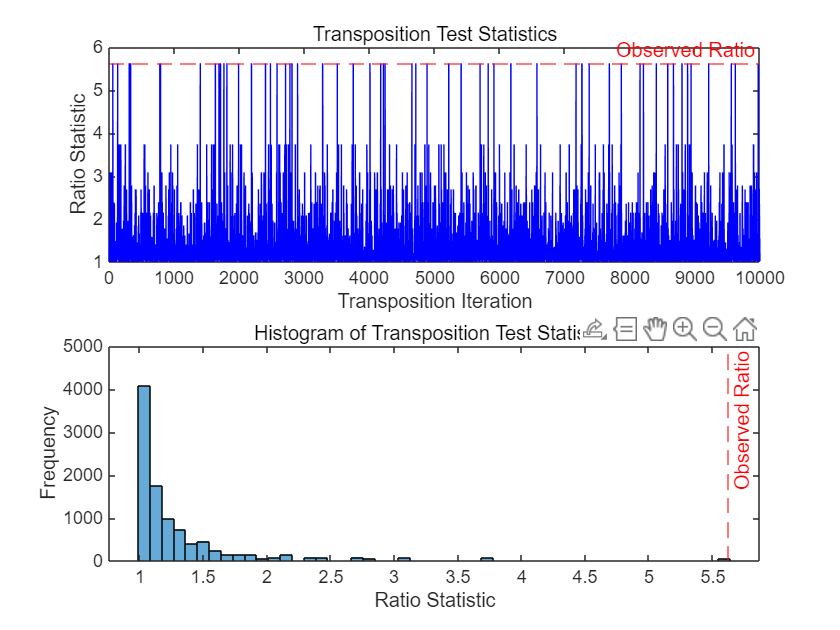

%% === Visualize Results ===
figure;
subplot(2,1,1);
plot(transStat, 'b');
hold on;
yline(observed_ratio, 'r--', 'Observed Ratio');
xlabel('Transposition Iteration');
ylabel('Ratio Statistic');
title('Transposition Test Statistics');

subplot(2,1,2);
histogram(transStat, 50);
hold on;
xline(observed_ratio, 'r--', 'Observed Ratio');
xlabel('Ratio Statistic');
ylabel('Frequency');
title('Histogram of Transposition Test Statistics');